# Unit 4.  In-Class Exercises

These exercises are to be performed with the in-class exercises.

## Problem 1:  Theoretical Error Rate Probability

Modify the code in the demo to compute the `BER` vs. `Es/N0`  for 16-QAM for AWGN and fading channel.  (Recall the demo measured the `BER` vs. `Eb/N0).  ` Remember that  you will want to plot the BER with `semilogy`. 

% Parameters
bitsPerSym = 4; % 4=16-QAM
nsym = 10000;

% TODO
%    ber = ...

% Create random bits to test
nbits = nsym*bitsPerSym;
bits = randi([0,1], nbits, 1);

% Modulate to M-QAM
M = 2^bitsPerSym;
s = qammod(bits,M,'UnitAveragePower', true, 'Input', 'bit');

% SNR levels to test
EsN0Test = (0:30)';
nsnr = length(EsN0Test);
Es = mean(abs(s).^2);

% Fading types to test
fadeTest = [false, true];
nfade = length(fadeTest);

% Initialize vectors
ber = zeros(nsnr,nfade);

% Loop 
for ifade = 1:nfade
    fade = fadeTest(ifade);
    
    for i = 1:nsnr
        % Generate fading channel
        if fade
            h = sqrt(1/2)*(randn(nsym,1) + 1i*randn(nsym,1));
        else
            h = ones(nsym,1);
        end
        rxSig0 = s.*h;
                
        % Add the noise
        EsN0 = EsN0Test(i);
        chan = comm.AWGNChannel('NoiseMethod', 'Signal to noise ratio (Es/No)',...
            'EsNo', EsN0, 'SignalPower', Es);
        rxSig = chan.step(rxSig0);
        
        % Equalize
        z = rxSig ./ h;
        
        % Demodulate
        bitsEst = qamdemod(z,M,'UnitAveragePower',true,'Output','bit');
        
        % Measure the BER
        ber(i,ifade) = mean(bitsEst ~= bits);
        fprintf(1, 'fading=%d EbN0=%7.2f BER=%12.4e\n', fade, EbN0, ber(i,ifade));
        
        % Break if zero since higher SNRs also be zero
        if (ber(i,ifade) == 0)
            break
        end
    end
end

fading=0 EbN0=  20.00 BER=  2.8547e-01
fading=0 EbN0=  20.00 BER=  2.6220e-01
fading=0 EbN0=  20.00 BER=  2.4088e-01
fading=0 EbN0=  20.00 BER=  2.1145e-01
fading=0 EbN0=  20.00 BER=  1.8510e-01
fading=0 EbN0=  20.00 BER=  1.6228e-01
fading=0 EbN0=  20.00 BER=  1.4240e-01
fading=0 EbN0=  20.00 BER=  1.1853e-01
fading=0 EbN0=  20.00 BER=  9.8950e-02
fading=0 EbN0=  20.00 BER=  7.6300e-02
fading=0 EbN0=  20.00 BER=  5.8800e-02
fading=0 EbN0=  20.00 BER=  4.1700e-02
fading=0 EbN0=  20.00 BER=  2.6850e-02
fading=0 EbN0=  20.00 BER=  1.7675e-02
fading=0 EbN0=  20.00 BER=  8.4500e-03
fading=0 EbN0=  20.00 BER=  4.8000e-03
fading=0 EbN0=  20.00 BER=  1.8500e-03
fading=0 EbN0=  20.00 BER=  7.5000e-04
fading=0 EbN0=  20.00 BER=  5.0000e-05
fading=0 EbN0=  20.00 BER=  0.0000e+00
fading=1 EbN0=  20.00 BER=  3.2165e-01
fading=1 EbN0=  20.00 BER=  3.0255e-01
fading=1 EbN0=  20.00 BER=  2.7770e-01
fading=1 EbN0=  20.00 BER=  2.6617e-01
fading=1 EbN0=  20.00 BER=  2.4197e-01
fading=1 EbN0=  20.00 BER

We will now compare the measured BER with the theoretical value.  For 16-QAM, the theoretical BER for an AWGN channel is

Use the Lemma in the lecture notes, to also compute the theoretical BER for a fading channel.  Plot the theoretical and measured values.

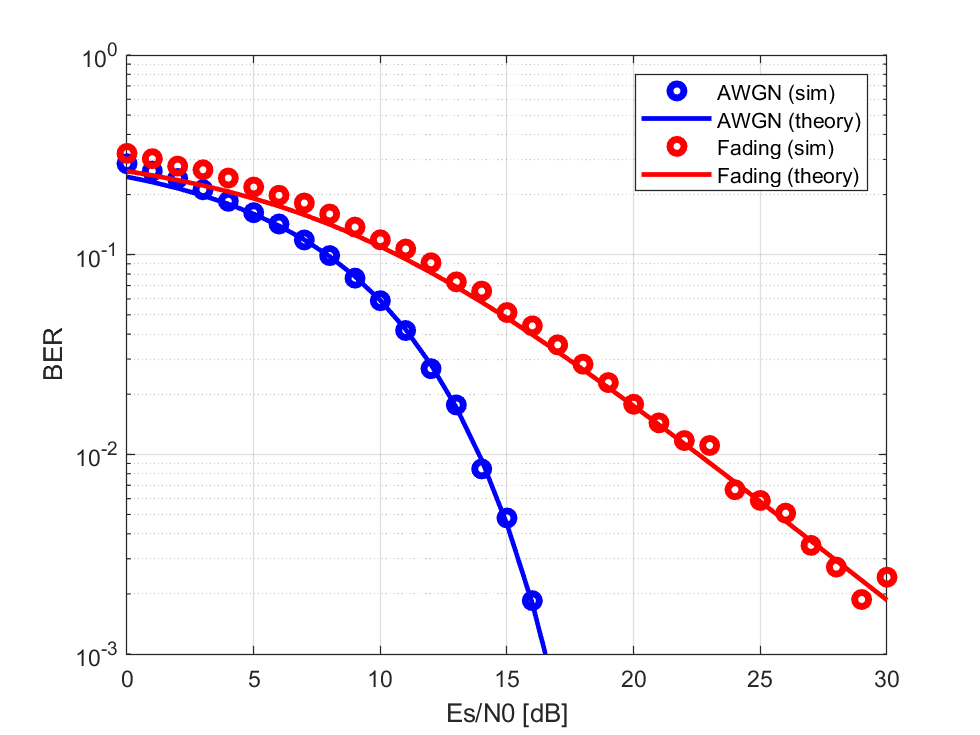

% TODO:
%   berTheoryAwgn = ...
%   berTheoryFading = ...
z = db2pow(EsN0Test)/5;
berTheoryAwgn = 3/4*qfunc(sqrt(z));
berTheoryFading = 3/8*(1-sqrt(z./(2+z))); 
    
% Plot the results
clf;
semilogy(EsN0Test, ber(:,1), 'bo', 'LineWidth', 3);
hold on;
semilogy(EsN0Test, berTheoryAwgn, 'b-', 'LineWidth', 2);
semilogy(EsN0Test, ber(:,2), 'ro', 'LineWidth', 3);
semilogy(EsN0Test, berTheoryFading, 'r-', 'LineWidth', 2);
hold off;

ylim([1e-3,1]);
xlabel('Es/N0 [dB]');
ylabel('BER');
grid on;
legend('AWGN (sim)', 'AWGN (theory)', 'Fading (sim)', 'Fading (theory)');

## Problem 2:  Outage Capacity in an Indoor Environment

In this problem, we will estimate the outage capacity in an indoor setting.  Our goal is to look at the effects of both large-scale and small-scale fading.

First generate `nx` locations in a box of size 30 x 40 m representing locations in some large indoor environment.  Assume an access point is located at the origin and compute a vector, `dist, `representing the distance in meters from the AP to each location.

% Parameters
nx = 10000;
xmax = [30,40];
d = 2;

% TODO
%    x = ...
%    dist = ...
x = rand(nx,d).*xmax;
dist = sqrt(sum(x.^2,2));


Next, use the `pathLoss3GPPInH` function below to compute random path losses for each location.  Based on the path losses and the parameters below compute the vector, `snrAvg` representing the average SNR for each location.  Plot the CDF of the SNRs. 

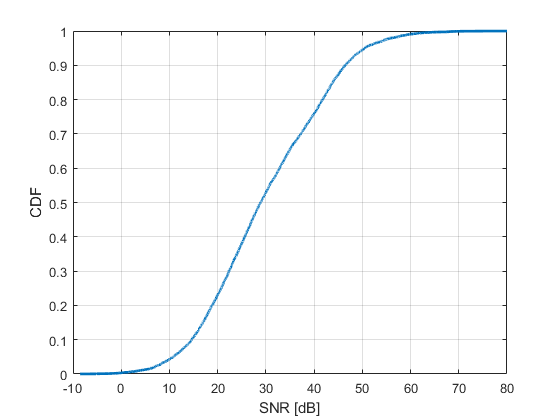

% Parameters 
fc = 2.3e9;  % Carrier freq in Hz
ptx = 15;    % TX power in dBm
nf = 10;     % Noise figure in dB
bw = 16e6;   % Bandwidth in Hz
Ekt = -174;  % Thermal noise in dBm/Hz before NF

% TODO
%    pl = pathLoss3GPPInH(...);
%    snrAvg = ...
pl = pathLoss3GPPInH(dist,fc);

snrAvg = ptx - pl - nf - Ekt -10*log10(bw);
p = (1:nx)/nx;
plot(sort(snrAvg), p, 'LineWidth', 2);
grid on;
xlabel('SNR [dB]');
ylabel('CDF');
xlim([-10,80]);

For each average SNR, `snrAvg(i),` generate a random instantaneous SNR, `snr(i)`, representing the average SNR with Rayleigh fading.  Plot the CDF of `snr` and `snrAvg`.   

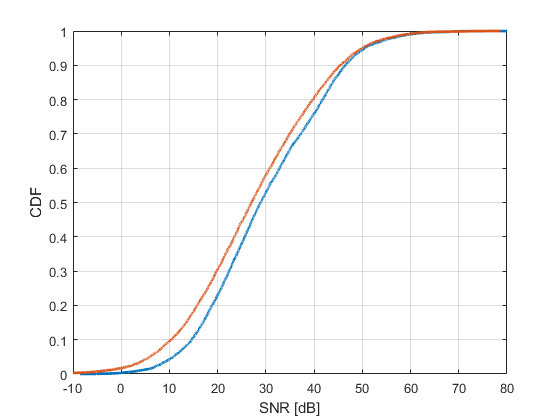

u = exprnd(1,nx,1);
snr = snrAvg + pow2db(u);

clf;
p = (1:nx)/nx;
plot(sort(snrAvg), p, 'LineWidth', 2);
hold on;
plot(sort(snr), p, 'LineWidth', 2);
hold off;
xlim([-20,40]);
xlabel('SNR [dB]');
ylabel('CDF');
xlim([-10,80]);
grid on;

For each SNR, assume the rate is given by the function `rate` below.  Plot the CDF of the rate for the average SNR and instantaneous SNR.  Note:

- `rate(snrAvg,bw)`:  Variation in rates with only large-scale variations

- `rate(snr,bw)`:  Variation in rates with large-scale variations and small scale fading

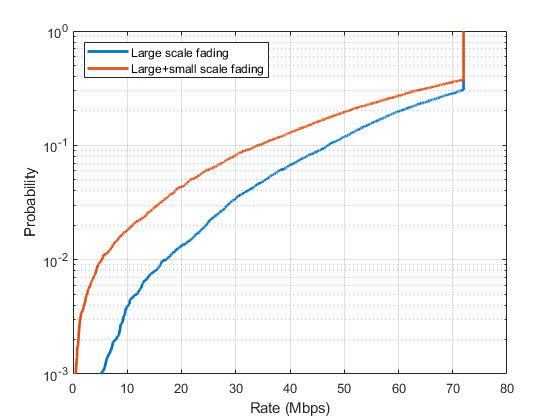

rate = @(snr, bw)  bw*min(4.5, 0.6*log2(1+db2pow(snr)));

% TODO
%   rateAvg = ...
%   rateFading = ...
rateAvg    = rate(snrAvg, bw);
rateFading = rate(snr, bw);

clf;
p = (1:nx)/nx;
semilogy(sort(rateAvg)/1e6, p, 'LineWidth', 2);
hold on;
semilogy(sort(rateFading)/1e6, p, 'LineWidth', 2);
hold off;
grid on;
ylim([1e-3, 1]);
legend('Large scale fading', 'Large+small scale fading', 'Location','NorthWest');
xlabel('Rate (Mbps)');
ylabel('Probability');

## Problem 3:  NR LDPC Coding

In this problem, we will simulate the LDPC encoding and decoding used in the 5G NR standard.  The MATLAB 5G Toolbox has an amazingly good implementation of this code, so we can just call it.  In the NR LDPC code, the number of input bits is given by:

where nrows is the number of rows in the LDPC base graph, and `nlift` is the so-called lifting factor which expands the graph to different block sizes.  We will use the following parameters:

bgn = 1;     % LDPC base graph number (1 or 2)
nrows = 22;  % number of rows in the base graph
nlift = 128; % lifting factor 
nbitsIn = nrows*nlift;  % number of input bits
maxNumIters = 8;        % max number of LDPC decode iterations

Using MATLABs `nrLDPCEncode` and `nrLDPC decode` functions to simulate the NR LDPC coding.  Using code similar to the demo, estimate the block error rate as a funciton of the SNR for Eb/N0 values in `EnN0Test`.  

% SNR values to test
EbN0Test = (0:0.25:3)';
ntest = length(EbN0Test);

% TODO:  Estimate BLER at each Eb/N0
%   bler = ...
bler = zeros(ntest,1);
for i = 1:ntest
    EbN0 = EbN0Test(i);
    nerr = 0;
    nblk = 0;
    
    while  (nerr < 100) && (nblk < 1e3)
        
        % Generate random bits
        bitsIn = randi([0,1], nbitsIn, 1);
        
        % Convolutionally encode the data
        bitsEnc = nrLDPCEncode(bitsIn,bgn);
               
        % QAM modulate
        txSig = qammod(bitsEnc,M,'InputType','bit','UnitAveragePower',true);         
        
        % Add noise 
        rate = nbitsIn/length(bitsEnc);
        Es = mean(abs(txSig).^2);
        EsN0 = EbN0 + 10*log10(rate*bitsPerSym);
        chan = comm.AWGNChannel('NoiseMethod', 'Signal to noise ratio (Es/No)', ...
            'EsNo', EsN0, 'SignalPower', Es);        
        rxSig = chan.step(txSig);
        
        % Compute LLRs
        noiseVar = Es*db2pow(-EsN0);
        llr = qamdemod(rxSig,M,'OutputType','approxllr', ...
            'UnitAveragePower',true,'NoiseVariance', noiseVar);        
       
        % Run Viterbi decoder
        maxNumIters = 8;
        bitsOut = nrLDPCDecode(llr, bgn, maxNumIters);
        %bitsOut = bitsOut(1:nbits);
        
        % Compute number of bit errors and add to the total
        if any(bitsIn ~= double(bitsOut))
            nerr = nerr + 1;
        end
        nblk = nblk + 1;
        
    end
    
    % Print results
    bler(i) = nerr / nblk;
    fprintf(1, 'EbN0 = %7.2f BLER=%12.4e\n', EbN0, bler(i));
    if nerr == 0
        break;
    end
end

EbN0 =    0.00 BLER=  1.0000e+00
EbN0 =    0.25 BLER=  1.0000e+00
EbN0 =    0.50 BLER=  1.0000e+00
EbN0 =    0.75 BLER=  1.0000e+00
EbN0 =    1.00 BLER=  1.0000e+00
EbN0 =    1.25 BLER=  1.0000e+00
EbN0 =    1.50 BLER=  1.0000e+00
EbN0 =    1.75 BLER=  1.0000e+00
EbN0 =    2.00 BLER=  1.0000e+00
EbN0 =    2.25 BLER=  1.0000e+00
EbN0 =    2.50 BLER=  1.0000e+00
EbN0 =    2.75 BLER=  1.0000e+00
EbN0 =    3.00 BLER=  1.0000e+00


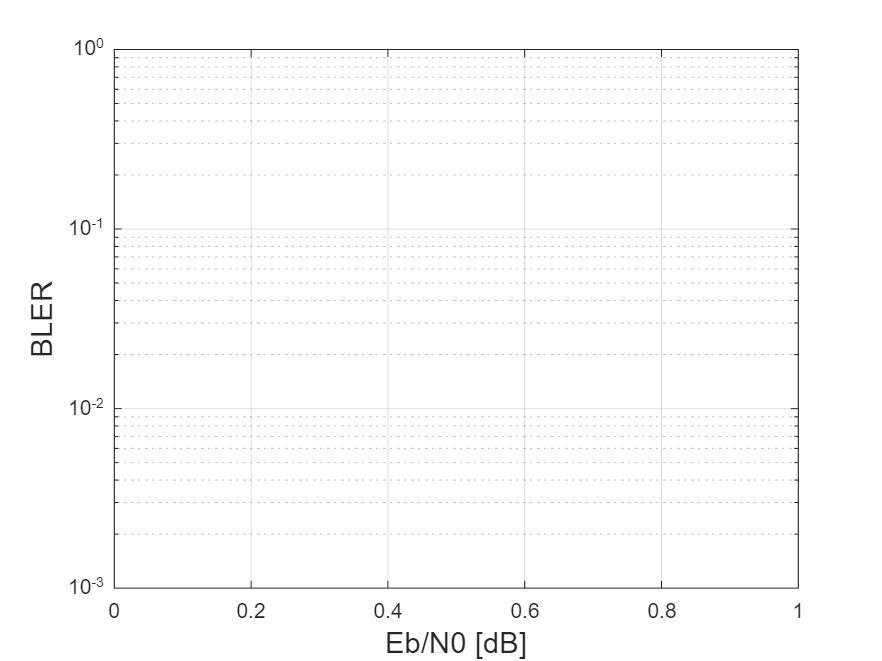

semilogy(EbN0Test, bler, 'o-', 'LineWidth', 2);
grid on;
ylim([1e-3,1]);
xlabel('Eb/N0 [dB]', 'FontSize', 14);
ylabel('BLER', 'Fontsize', 14);

function pl = pathLoss3GPPInH(dist,fc)
    % pathLoss3GPPInH:  Generates random path loss 
    % 
    % Samples the path loss using the 3GPP-InH model

    % Compute the median path losses for LOS and NLOS
    pllos = 32.4 + 17.3*log10(dist) + 20*log10(fc/1e9);
    plnlos = 17.3 + 38.3*log10(dist) + 24.9*log10(fc/1e9);
    
    % Add shadowing
    w = randn(size(dist));
    pllos = pllos + 3*w;
    plnlos = plnlos + 8.03*w;
    
    % Compute probability of being LOS or NLOS
    plos = min( exp(-(dist-1.2)/4.7), 1);
    plos = max( 0.32*exp(-(dist-6.5)/32.6), plos);
    
    % Select randomly between LOS and NLOS path loss
    u = (rand(size(dist)) < plos); 
    pl = u.*pllos + (1-u).*plnlos;
    
end